# Engineering math project

## Pantea Farhadi

### Section 2

#### 2.3 Questions:

- 2D fourier transform is a transformation from spatial domain to frequency domain, which is of form:


$$\int\int f(x, y)exp(-i(k_{x}x + k_{y}y))dxdy$$


         2. Each point in K-space represents the frequrency in that region, each point in K-space contains information about phase and frequency of pixels in the final image.  

         3. Each point in the K-space is corresponding to given images as follows:            

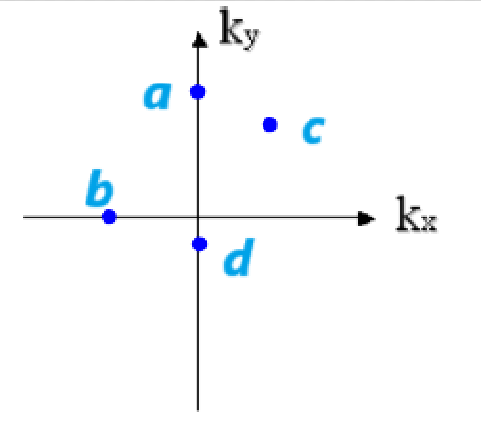

          4. By deleting high frequency bases in the k-space the picture will maintain its original structure, reagarding that high frequecy is corresponding to details, we'll just lose details. On the other hand, by deleting low frequency bases we will lose most of the information of image and its main structure will be unrecognizable.

### Section 3

### 3.2 Questions:

- **Inverse Fourier transform**: In the context of MRI, the process of reconstructing k-space data into an image involves the use of the inverse Fourier transform. The raw data obtained from the MRI     scanner is in the form of k-space, which contains information about the spatial frequency content of the image. To obtain the spatial domain image data from the k-space data, the inverse Fourier transform is applied.The inverse Fourier transform is a mathematical operation that converts the frequency domain data (k-space) into spatial domain data (image). It essentially reverses the process of the Fourier transform, allowing the spatial information to be extracted from the frequency domain data.The inverse Fourier transform is applied to each line of k-space data to generate the corresponding spatial domain data. This process is repeated for all the lines of k-space data, resulting in the reconstruction of the complete spatial domain image. **Filtered back projection**, on the other hand, is used in CT imaging to reconstruct an image from the raw projection data obtained from multiple angles around the object. The process involves applying a filter to the back-projected data to improve the quality of the reconstructed image. This technique is not directly applicable to MRI image reconstruction from k-space data. Therefore, in the context of MRI, the reconstruction of an image from k-space data primarily involves the use of Fourier transformation and related processing techniques, rather than filtered back projection.

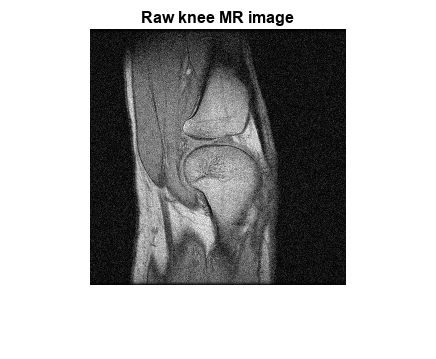

load('rawkneedata.mat');
figure;
noisy = scalingAns(inverse(dat));
imshow(noisy);
title("Raw knee MR image");

         4. We know that Fourier transform of an image gives its k-space bases, so by **inverse Fourier transform** we'll come up with the raw image. Also its's worth noting that using "mat2gray" function will clarify image by scaling the elements in the matrix from 0(black) to 1(white).

        5. In **medical imaging** the most important source of noise is the patient's body (RF emission due to thermal motion). The whole measurement chain of the MR scanner (coils, electronics...) also contributes to the noise. For eample, when the gradient coils receive electrical pulses, they generate a magnetic field. Each pulse makes the coils vibrate and create loud noises. Briefly speaking main noises in MRI imaging are  related to noises in gradient coil, radiofrequency coil, mechanical vibration, scanner room, patient motion, electronic components and gradients.

### Section 4

        1. Filters are generally used in digital image processing to modify or enhance image properties and/or to extract valuable information from the pictures such as edges, corners, and blobs. They are used for tasks such as blurring, noise reduction, smoothing, sharpening, and edge detection. We can recognize the type of filter by plotting its histogram after being applied on a noisy image, the effect of each filter is noted bellow:

- **Smoothing Filters **: Smoothing filters reduce the high-frequency components in the image, which can lead to a decrease in the overall contrast. This often results in a broader distribution of pixel intensities in the histogram, with a reduction in the number of extreme values.

- **Sharpening Filters**: Sharpening filters enhance the high-frequency components in the image, which can lead to an increase in the overall contrast. This often results in a narrower distribution of pixel intensities in the histogram, with an increase in the number of extreme values.

- **Edge Detection Filters**: Edge detection filters highlight the edges and boundaries in the image, which can lead to changes in the distribution of pixel intensities around these edges. This can result in peaks and valleys in the histogram corresponding to the edges in the image.

- **Noise Reduction Filters**: Filters designed to reduce noise in the image can smooth out small variations in pixel intensities, leading to a more uniform distribution in the histogram.

- **Color Space Conversion**: When converting an image from one color space to another (e.g., RGB to grayscale), the histogram will be affected by the transformation, potentially changing the distribution of pixel intensities.

- 1) The fundamental purpose of a **mean filter** is to replace each pixel value in an image or each sample in a signal with the average value of its neighboring pixels or samples within a defined window or kernel, the mean filter is effective in reducing the impact of random noise and small-scale variations in the input signal or image.

- 1) A **Gaussian filter**, also known as a Gaussian smoothing filter, is a type of linear filter commonly used in digital signal processing and image processing for smoothing and noise reduction. It is based on the Gaussian function, which is a bell-shaped curve that represents a probability distribution.

- 1) A **median filter** is a non-linear digital filtering technique commonly used to remove noise from an image or signal. It is effective at removing noise in smooth patches or regions, while preserving edges, which are critical for the visual appearance of images. The filter works by replacing each pixel's value with the median value of the neighboring pixels.

Due to linearity of Gauss and mean filter they can be represneted as a kernel convolution but median filter is non linear so it's applied in other ways.

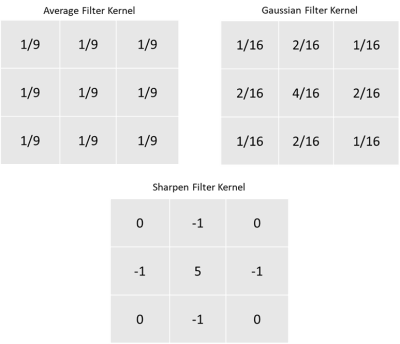 

- **Mean Filter:**

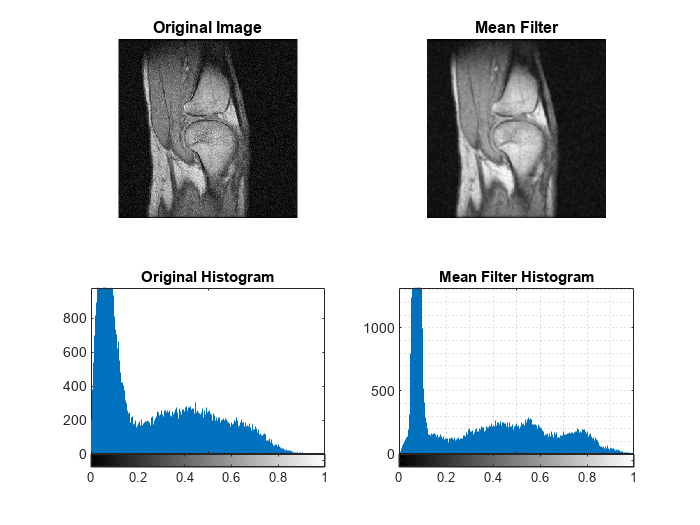

figure;
subplot(2, 2, 1);
noisy = scalingAns(inverse(dat));
imshow(noisy);
title("Original Image");

subplot(2, 2, 2)
meanFilter = scalingAns(meanPass(inverse(dat), 3));
imshow(meanFilter);
title("Mean Filter")

subplot(2, 2, 3)
grid minor
histogram(noisy);
hold on
title("Original Histogram")


subplot(2, 2, 4)
histogram(meanFilter);
hold on
grid minor
title("Mean Filter Histogram")

As seen in the histogram filter resluts in enhancement or suppression of specific frequency components, which can have various effects on the image's appearance and characteristics.

        2. **Gauss Filter:**

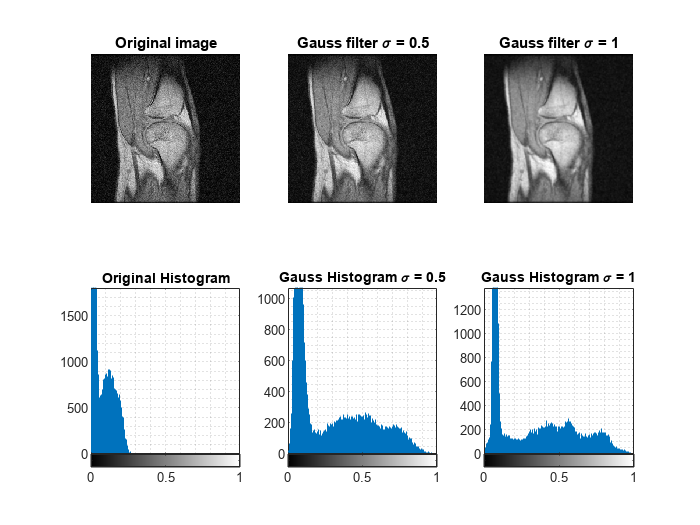

figure;
subplot(2, 3, 1);
noisy = scalingAns(inverse(dat));
imshow(noisy);
title("Original image");

subplot(2, 3, 2);
GaussFilter1 = scalingAns(GaussPass(inverse(dat), 0.5, 5));
imshow(GaussFilter1);
title("Gauss filter \sigma = 0.5")


subplot(2, 3, 3);
GaussFilter2 = scalingAns(GaussPass(inverse(dat), 1, 5));
imshow(GaussFilter2);
title("Gauss filter \sigma = 1");

subplot(2, 3, 4)
histogram(inverse(dat));
hold on
grid minor
title("Original Histogram")

subplot(2, 3, 5);
histogram(GaussFilter1);
hold on
grid minor
title("Gauss Histogram \sigma = 0.5")

subplot(2, 3, 6)
histogram(GaussFilter2);
hold on
grid minor
title("Gauss Histogram \sigma = 1")

As we can see, Gauss filter has smoothing effects, it's originally used for blurring images. From the histogram it can be concluded that the bigger the sigma is the smaller the diversity of colors will become, which means bigger regions will have common color. Also it can easily be shown that increasing the size of kernel will enhance the smoothening effect of filter, which is a consequence of larger sampling area.

        3.**Median Filter:**

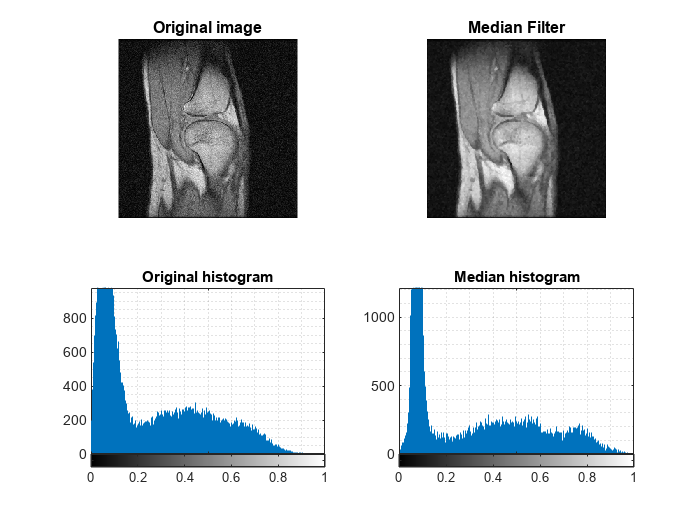

figure;
subplot(2, 2, 1);
noisy = scalingAns(inverse(dat));
imshow(noisy);
title("Original image");

subplot(2, 2, 2);
medianFilter = scalingAns(medianPass(inverse(dat)));
imshow(medianFilter);
title("Median Filter")

subplot(2, 2, 3);
histogram(noisy);
hold on
grid minor
title("Original histogram");

subplot(2, 2, 4)
histogram(medianFilter);
hold on
grid minor
title("Median histogram")

Duo to non linear behaviour of median filter, its effect is not the same on the whole region but the best for enhancing middle values since the distributaion is directed toward the middle. This filter is moslty used fot reducing salt and pepper noises since it will replace value at the center of a square with the median of neighbours.

        4. **NLM Filter:**

Generally, non-local filters compare the area containing the noisy pixel and the neighboring area to obtain a weight, and subsequently filters using a Gaussian kernel and an average value. Among the noise reduction algorithms using the non-local filter method, the total variation-based method and non-local means (NLM) method were introduced and they are widely used in the field of MR imaging. In particular, the NLM noise reduction algorithm was proposed to minimize the loss of the inherent information in the image and to selectively remove only the noise. This algorithm measures the similarity of the intensity and edge information in an image after setting areas with the same sized mask located around the region of interest (ROI). Additionally, the higher the degree of similarity, the higher the assigned weight used during the image processing


$$NLM|I(m)| = \sum_{n\in N_{m}}w(N_{m}, N_{n})I(n)(w(N_{m}, N_{n} ) = \frac{1}{Z(m)}\exp(\frac{-d}{h^2}))$$


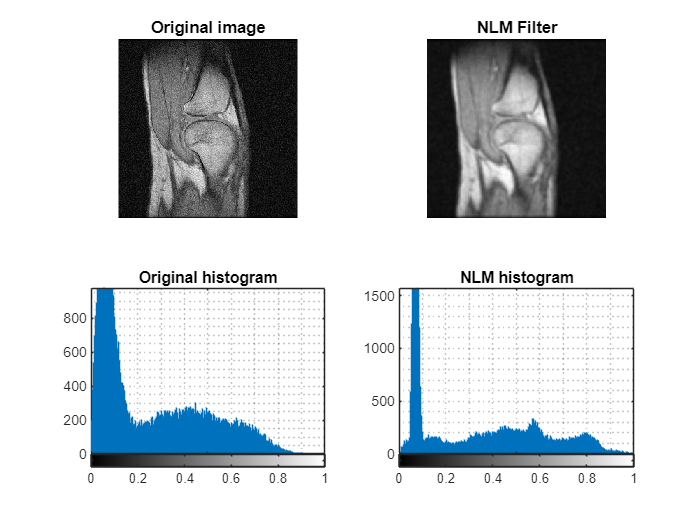

figure;
subplot(2, 2, 1);
noisy = scalingAns(inverse(dat));
imshow(noisy);
title("Original image");

subplot(2, 2, 2);
NLMFilter = scalingAns(NLMPass(inverse(dat), 5, 5));
imshow(NLMFilter)
title("NLM Filter")

subplot(2, 2, 3);
histogram(noisy);
hold on
grid minor
title("Original histogram");

subplot(2, 2, 4);
histogram(NLMFilter);
hold on
grid minor
title("NLM histogram");

The effect of noise reduction by both smoothing and edge detecting can easily be seen in the histogram since the histogram is more densed after applying the filter.

## Evaluation

For evaluating the effect of each filter we can use SNR and PSNR metrics, which are based on the signal power and noise power. **Peak signal-to-noise ratio** (**PSNR**) is an engineering term for the ratio between the maximum possible power of a signal and the power of corrupting noise that affects the fidelity of its representation. **Signal-to-noise ratio** (**SNR** or **S/N**) is a measure that compares the level of a desired signal to the level of background noise. SNR is defined as the ratio of signal power to noise power, often expressed in db.

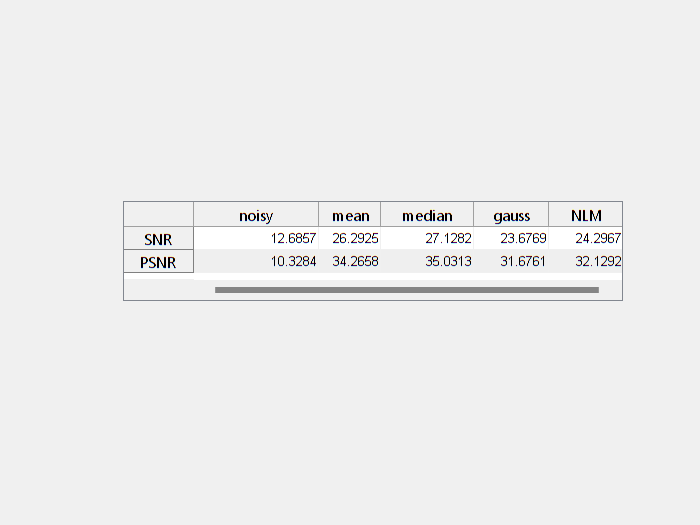

SNRData = zeros(1, 4);
PSNRData = zeros(1, 4);
noiseLess = scalingAns(imread('kneeMRI.jpg'));

SNRData(1) = SNR(noisy, noiseLess);
SNRData(2) = SNR(meanFilter, noiseLess);
SNRData(3) = SNR(GaussFilter2, noiseLess);
SNRData(4) = SNR(medianFilter, noiseLess);
SNRData(5) = SNR(NLMFilter, noiseLess);

PSNRData(1) = PSNR(inverse(dat), noiseLess);
PSNRData(2) = PSNR(meanFilter, noiseLess);
PSNRData(3) = PSNR(GaussFilter2, noiseLess);
PSNRData(4) = PSNR(medianFilter, noiseLess);
PSNRData(5) = PSNR(NLMFilter, noiseLess);

figure
Data = [SNRData; PSNRData];
colName = ["noisy", "mean", "median", "gauss", "NLM"];
Table(Data, colName);

The result indicates that median filter has had the best performance, better performance of median filter can be justified by the nature of noise in image which is named as salt and pepper noise. This noise epears when there are random pixels in picture that are black or white (like salt and pepper in a food), median filter deletes these noise very well since it replaces the central element by median of its neighbour.

## Functions

function ans = inverse(image)
    ans = abs(ifftshift(ifft2(image)));
end


function histogram(pic)
    imhist(pic);
end

function ans = meanPass(pic, sz)
    kernel = ones(sz, sz) / (sz * sz);
    originalSize = [size(pic, 1), size(pic, 2)];

    paddedImage = padarray(pic, [floor(sz/2) floor(sz/2)], 'replicate'); %paddding image because of boundary effects
    paddedAns = conv2(paddedImage, kernel, 'same');
    ans = paddedAns(floor(sz/2)+1:floor(sz/2)+originalSize(1), floor(sz/2)+1:floor(sz/2)+originalSize(2));
end

function ans = GaussPass(pic, sigma, sz)
    ind = -floor(sz/2) : floor(sz/2);
    originalSize = [size(pic, 1), size(pic, 2)];
    [X Y] = meshgrid(ind, ind);
    
    %// Create Gaussian Mask
    kernel = exp(-(X.^2 + Y.^2) / (sigma*sigma*2));
    
    %// Normalize so that total area (sum of all weights) is 1
    kernel = kernel / sum(kernel(:));
    paddedImage = padarray(pic, [floor(sz/2) floor(sz/2)], 'replicate'); %paddding image because of boundary effects sz = 3
    paddedAns = conv2(paddedImage, kernel, 'same');
    ans = paddedAns(floor(sz/2)+1:floor(sz/2)+originalSize(1), floor(sz/2)+1:floor(sz/2)+originalSize(2));
end

function ans = medianPass(pic)
    realPart = real(pic);
    imagPart = imag(pic); 

    realAns = medfilt2(realPart, [3 3]);
    imagAns = medfilt2(imagPart, [3 3]);

    % Combine the filtered real and imaginary parts into a complex matrix
    ans = complex(realAns, imagAns);
end

function ans = NLMPass(pic, h, windowSize)
    ans = imnlmfilt(pic, 'DegreeOfSmoothing', h, 'SearchWindowSize', windowSize);
end

function snr = SNR(noisyImg, initImg)
    sigPow = sum(noisyImg.^2, 'all');
    noisePow = sum((noisyImg - initImg).^2, 'all');

    snr = 10*log10(sigPow / noisePow);
end

function psnr = PSNR(noisyImg, initImg)
    n = size(initImg, 1);
    m = size(initImg, 2);
    
    MSE = sum((noisyImg - initImg).^2, 'all')/(n*m); % I used the absolute value of data in this part
    psnr = 10*log10(max(initImg, [], 'all')^2 / MSE);

end

function Table(data, colName)
 figure
 t = uitable('Data', data, 'ColumnName', {colName(1), colName(2), colName(3), colName(4), colName(5)}, 'ColumnWidth' ,{100, 50, 75}, 'RowName', {'SNR', 'PSNR'}, 'Position', [100, 180, 400, 80]);
end

function ans = scalingAns(pic)
    ans = mat2gray(abs(pic));
end